# 航空機ターボエンジンの残存耐用時間（RUL）予測

Copyright 2021 Michio Inoue

このコードでは論文で Model Health Parameters と紹介されている変数と、エンジンの状態評価に使用される変数として次の４つも使用する。T48, SmFan, SmLPC, SmHPC

At present, the N-CMAPSS dataset contains eight sets of data from 128 units and seven different failure modes affecting the flow (F) and/or efficiency (E) of all the rotating sub-components. Table 2 provides an overview of flight classes and failure modes for each of the sets of data provided 

とある通り、DS 番号によって入れ込まれている故障モードは様々なようなので、それぞれで挙動が異なることが想定される。変数名の一覧は以下の通り。

- fan_eff_mod: Fan efficiency modifier (-)

- fan_flow_mod: Fan flow modifier (-)

- LPC_eff_mod: LPC efficiency modifier (-)

- LPC_flow_mod: LPC flow modifier (-)

- HPC_eff_mod: HPC efficiency modifier (-)

- HPC_flow_mod: HPC flow modifier (-)

- HPT_eff_mod: HPT efficiency modifier (-)

- HPT_flow_mod: HPT flow modifier (-)

- LPT_eff_mod: LPT efficiency modifier (-)

- LPT_flow_mod: LPT flow modifier (-)

## 事前準備

ディレクトリ情報の確保

clear
settings = jsondecode(fileread('../settings.json'));
datadir = settings.PROCESSED_DATA_DIR

datadir = '../data/processed/'

modeldir = settings.MODEL_DIR

modeldir = '../models/'

subdir = settings.SUBMISSION_DIR

subdir = '../submissions/'

DS (Data Set?) 名定義

fileID = ["DS01-005", "DS02-006", "DS03-012", "DS04", "DS05", ...
    "DS06", "DS07", "DS08a-009", "DS08c-008"];

変数名: 各 cycle での平均値を使用するので、平均値の変数名定義

eff_mod_list = ["fan_eff_mod";"fan_flow_mod";"LPC_eff_mod";"LPC_flow_mod";...
    "HPC_eff_mod";"HPC_flow_mod";"HPT_eff_mod";"HPT_flow_mod";
    "LPT_eff_mod";"LPT_flow_mod"];
meaneff_mod_list = "mean" + eff_mod_list;

% 追加で使用する変数も４つ追加（エンジンの状態評価に使用される変数）
var_list = [eff_mod_list; "T48";"SmFan";"SmLPC";"SmHPC"];
meanvar_list = "mean" + var_list;

## 平均値計算

事前にデータは cycle 単位で分割し保存しているとします。loadData.mlx 参照。ここではさらに各 Model Health Parameter の cycle 単位での平均値を計算してデータ保存しておきます。

% 一度作成すればOK
if ~exist(fullfile(datadir, "train_DS01-005Unwrap_OtherParam.mat"),'file')
    % 各fileID毎に処理
    for ii=1:length(fileID) % 1 min
        load(fullfile(datadir, "train_" + fileID(ii) + "Unwrap.mat"),"dTrainUnwrap");
        % Unit 毎に処理
        for jj=1:height(dTrainUnwrap)
            dUnit = dTrainUnwrap.data{jj};

            % 平均値計算
            for kk=1:length(var_list)
                dUnit.("mean" + var_list(kk)) ...
                    = cellfun(@(x) mean(x.(var_list(kk))), dUnit.data);
            end
            dUnit = removevars(dUnit,'data'); % 元時系列データは重いので削除
            dTrainUnwrap.data{jj} = dUnit;
        end
        % 保存
        save(fullfile(datadir, "train_" + fileID(ii) + "Unwrap_OtherParam.mat"),"dTrainUnwrap");

        % test データでも同様に処理
        load(fullfile(datadir, "test_" + fileID(ii) + "Unwrap.mat"),"dTestUnwrap");
        % Unit 毎に処理
        for jj=1:height(dTestUnwrap)
            dUnit = dTestUnwrap.data{jj};

            % 平均値計算
            for kk=1:length(var_list)
                dUnit.("mean" + var_list(kk)) ...
                    = cellfun(@(x) mean(x.(var_list(kk))), dUnit.data);
            end
            tmp = dUnit{:,6:end};
            dUnit = removevars(dUnit,'data'); % 元時系列データは重いので削除
            dTestUnwrap.data{jj} = dUnit;
        end
        % 保存
        save(fullfile(datadir, "test_" + fileID(ii) + "Unwrap_OtherParam.mat"),"dTestUnwrap");

    end
end

## 特徴量作成

以下でモデル学習に使用するためのデータを作成するが以下の点に注意。

- Model Health Parameter は DS によって値を持つ変数が異なることが論文に記載されている。ただ DS02-006 の Unit 2, 5, 10 については１つの Health Parameter だけに変動が見られ、DS01-005 と同じ様相であるため、変数 DS は DS01-005 とする。

- また RUL が 100 である unit は、100 回目の実験で打ち切られた（すなわちまだ寿命ではない）データである可能性があるため、Fc = 1 のケース（本来寿命が長くなりがちのケース）で RUL = 100 のデータは学習データから取り除く。

- その他 Health Parameter の値については移動平均で滑らかにする、初期変動分を調整する、abnormal degredation 時（hs = 0）の傾きだけを別途評価するための変数を作成するなどの処理をする。

trainData = [];
testData = [];
% fileID (DS) 毎に処理
for ii=1:length(fileID)
    % 処理ずみのデータを読み込み
    load(fullfile(datadir, "train_" + fileID(ii) + "Unwrap_OtherParam.mat"),"dTrainUnwrap");

    % Unit 毎に処理
    for jj=1:height(dTrainUnwrap)
        dUnit = dTrainUnwrap.data{jj};

        % 学習データから取り除く
        if height(dUnit) == 100 && unique(dUnit.Fc) == 1
            continue
        end

        dUnit.DS = repmat(fileID(ii),height(dUnit),1);
        dUnit.Unit = repmat(dTrainUnwrap.unit(jj),height(dUnit),1);

        % DS02-006 の unit = 2,5,10 は DS01-005 として取り扱う
        if unique(dUnit.DS == 'DS02-006') && ...
                (dUnit.Unit(1) == 2 || dUnit.Unit(1) == 5 || dUnit.Unit(1) == 10)
            dUnit.DS = repmat(fileID(1),height(dUnit),1);
        end

        % meaneff_mod_list の変数について手を加える
        tmp = dUnit{:,meaneff_mod_list};
        tmp = movmean(tmp,5); % 移動平均

        % 初期変動を取り除く処理（線形近似をして切片分を調整）
        for kk=1:size(tmp,2)
            p = polyfit(1:10,tmp(1:10,kk),1);
            tmp(:,kk) = tmp(:,kk) - p(2);
        end

        % 全 DS 間で比べられるよう統合指標作成（ざっくり第一主成分）
        [~,scores,~] = pca(tmp);

        dUnit{:,meaneff_mod_list} = tmp;
        dUnit.score1 = scores(:,1)-scores(1,1);

        % abnormal degregation の傾きを評価
        % ここでは test data に合わせて、40 cycle 目までのデータを使用
        idxh0init = find(dUnit.hs == 0,1);
        idxh0fint = find(dUnit.cycle == 40,1);
        x = dUnit.cycle(idxh0init-3:idxh0fint);
        y = dUnit.score1(idxh0init-3:idxh0fint);

        x0 = [0.002,1.5];
        opts = optimoptions('fmincon','TypicalX',x0,'Display',"none");
        p = fmincon(@(a)myfun(a,[x-x(1),y-y(1)]),x0,[],[],[],[],[0.0001,1.4],[0.003,1.6],[],opts);

        % 係数も特徴量として使用する
        dUnit.p1 = p(1)*ones(height(dUnit),1);
        dUnit.p2 = p(2)*ones(height(dUnit),1);


        dTrainUnwrap.data{jj} =  dUnit;
        dTrainUnwrap.p1(jj) = p(1);
        dTrainUnwrap.p2(jj) = p(2);

        trainData = [trainData; dUnit]; %#ok<AGROW> 

    end

    % 以下 test data に対しても同様の処理
    % 処理ずみのデータを読み込み
    load(fullfile(datadir, "test_" + fileID(ii) + "Unwrap_OtherParam.mat"),"dTestUnwrap");

    % Unit 毎に処理
    for jj=1:height(dTestUnwrap)
        dUnit = dTestUnwrap.data{jj};
        dUnit.DS = repmat(fileID(ii),height(dUnit),1);
        dUnit.Unit = repmat(dTestUnwrap.unit(jj),height(dUnit),1);

        tmp = dUnit{:,meaneff_mod_list};

        tmp = movmean(tmp,5);

        for kk=1:size(tmp,2)
            p = polyfit(1:10,tmp(1:10,kk),1);
            p(2);
            tmp(:,kk) = tmp(:,kk) - p(2);
        end

        [~,scores,~] = pca(tmp);

        dUnit{:,meaneff_mod_list} = tmp;
        dUnit.score1 = scores(:,1)-scores(1,1);

        mvscore = movmean(dUnit.score1,1);
        idxh0init = find(dUnit.hs == 0,1);
        idxh0fint = find(dUnit.cycle == 40,1);
        x = dUnit.cycle(idxh0init-3:idxh0fint);
        y = mvscore(idxh0init-3:idxh0fint);


        x0 = [0.002,1.5];
        opts = optimoptions('fmincon','TypicalX',x0,'Display',"none");
        p = fmincon(@(a)myfun(a,[x-x(1),y-y(1)]),x0,[],[],[],[],[0.0001,1.4],[0.003,1.6],[],opts);
        dUnit.p1 = p(1)*ones(height(dUnit),1);
        dUnit.p2 = p(2)*ones(height(dUnit),1);

        dTestUnwrap.data{jj} =  dUnit;
        dTestUnwrap.p1(jj) = p(1);
        dTestUnwrap.p2(jj) = p(2);
        testData = [testData; dUnit]; %#ok<AGROW> 

    end
end


こんな様子のデータです。

head(trainData)

ans = 8×23 table
    cycle    Y     Fc    hs    meanfan_eff_mod    meanfan_flow_mod    meanLPC_eff_mod    meanLPC_flow_mod    meanHPC_eff_mod    meanHPC_flow_mod    meanHPT_eff_mod    meanHPT_flow_mod    meanLPT_eff_mod    meanLPT_flow_mod    meanT48    meanSmFan    meanSmLPC    meanSmHPC        DS        Unit      score1           p1          p2  
    _____    __    __    __    _______________    ________________    _______________    ________________    _______________    ________________    _______________    ________________    _______________    ________________    _______    _________    _________    _________    __________    ____    ___________    __________    ______

      1      74    3     1            0                  0                   0                  0                   0                  0              -2.5279e-05             0                   0                  0            1612.6      19.036       8.4587       28.487      "DS01-005"     2                0    0

保存

save(fullfile(datadir,'trainData.mat'),'trainData')
save(fullfile(datadir,'testData.mat'),'testData')

## モデル学習

load(fullfile(datadir,'trainData.mat'),'trainData')
load(fullfile(datadir,'testData.mat'),'testData')

% 変数選択で試行錯誤しやすいようこの形にしておく
% （ここでは unit 番号を削るのみ）
trainDSUnitID = string(trainData.DS) + string(trainData.Unit);
% 学習用
subtrainData = trainData(:,["cycle","Y",meanvar_list',"Fc","hs","DS","p1","p2","score1"]);
% テスト用
subtestData = testData(:,["cycle",meanvar_list',"Fc","hs","DS","p1","p2","score1"]);

### アンサンブル決定木の学習

以下のハイパーパラメータもベイズ最適化でチューニングします。

- [`Method`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#bvcj_tw-1-Method) — 使用可能な方式は `'Bag'` または `'LSBoost'` です。

- [`NumLearningCycles`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#bvcj_tw-1-NumLearningCycles) — `fitrensemble` は、既定では範囲 `[10,500]` の対数スケールで、正の整数を探索します。

- [`LearnRate`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#mw_0b7f0d4a-2aae-4c52-a876-a6cb06c15ba4) — `fitrensemble` は、既定では範囲 `[1e-3,1]` の対数スケールで、正の実数を探索します。

- [`MinLeafSize`](https://www.mathworks.com/help/releases/R2021a/stats/fitrtree.html#bt6cr84-MinLeafSize) — `fitrensemble` は、範囲 `[1,max(2,floor(NumObservations/2))]` の対数スケールで整数を探索します。

単純に交差検定のためのデータ分割を行うだけなら 'OptimizeHyperparameters' オプションを 'auto' に設定するだけで良い（以下例）

ただ、今回は同じ unit からのデータが学習用・検証用データ両方に存在しないように分ける必要があるので、以下のコード。

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      5.9987 |      1.9737 |      5.9987 |      5.9987 |      LSboost |           33 |     0.027547 |          516 |
|    2 | Accept |      7.4055 |      1.3599 |      5.9987 |      6.0745 |      LSboost |           53 |    0.0018978 |            2 |
|    3 | Best   |      4.1443 |      11.779 |      4.1443 |      4.1447 |      LSboost |          468 |     0.051433 |           32 |
|    4 | Best   |      4.0419 |      1.6909 |      4.0419 |   

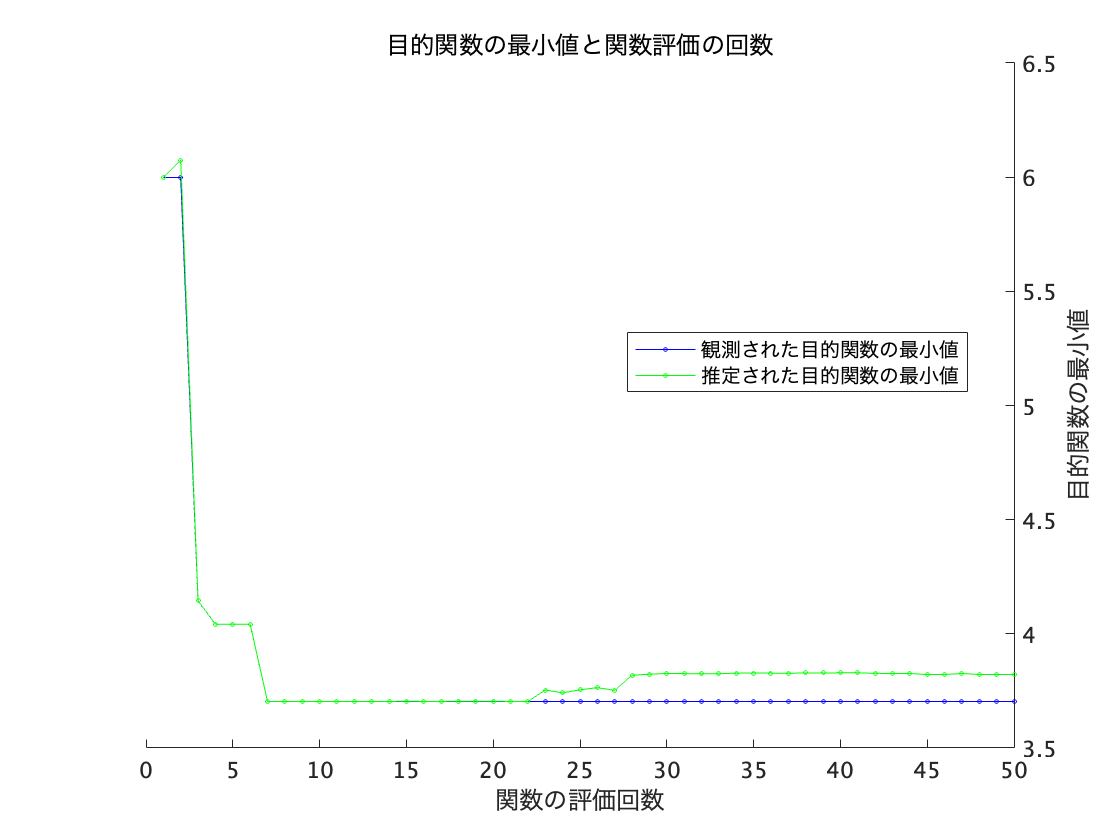


__________________________________________________________
最適化が完了しました。
MaxObjectiveEvaluations の 50 に達しました。
関数の評価回数の合計: 50
経過時間の合計: 297.6322 秒
目的関数の評価時間の合計: 269.4538

最適な観測実行可能点:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             21             0.2869          10     

観測された目的関数値 = 3.7037
推定される目的関数値 = 3.822
関数の評価時間 = 0.89814

最適な推定実行可能点 (モデルに基づく):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             21             0.2869          10     

推定される目的関数値 = 3.822
推定される関数評価時間 = 0.7578



rng(0)% 乱数シード固定（再現用）
NumObservations = height(subtrainData); % データ数
NumPredictors = width(subtrainData)-1; % 説明変数の数

% ベイズ最適化でチューニングする変数の定義
Method = optimizableVariable('Method',["Bag","LSboost"],'Type','categorical');
NumLearningCycles = optimizableVariable('NumLearningCycles',[10,500],'Transform','log','Type',"integer");
LearnRate = optimizableVariable('LearnRate',[1e-3,1],'Transform','log');
MinLeafSize = optimizableVariable('MinLeafSize',[1,max(2,floor(NumObservations/2))],'Transform','log','Type',"integer");

vars = [Method,NumLearningCycles,LearnRate,MinLeafSize];

% 目的関数定義（交差検定の誤差が目的変数）
fun = @(vars) myBayesGroup(vars,subtrainData,trainDSUnitID);

% UseParallel, true で並列処理（Parallel Computing Toolbox) できるが
% 結果の再現性が失われてしまうのでここでは並列処理なし
results = bayesopt(fun,vars,'UseParallel',false,...
    'AcquisitionFunctionName',"expected-improvement-plus",...
    'MaxObjectiveEvaluations',50);

最適値において再学習

optvars = results.XAtMinEstimatedObjective;
mdl = myBayesOptModel(optvars,subtrainData);

## 変数の重要度評価

tmp = predictorImportance(mdl);
[~,idx] = sort(tmp,'descend');
mdl.PredictorNames(idx)'

ans = 21×1 の cell 配列
    {'score1'          }
    {'cycle'           }
    {'meanHPT_eff_mod' }
    {'p1'              }
    {'meanLPT_eff_mod' }
    {'meanSmLPC'       }
    {'meanLPT_flow_mod'}
    {'hs'              }
    {'DS'              }
    {'meanHPC_flow_mod'}
    {'p2'              }
    {'meanHPC_eff_mod' }
    {'meanHPT_flow_mod'}
    {'meanfan_eff_mod' }
    {'meanLPC_flow_mod'}
    {'meanfan_flow_mod'}
    {'meanSmHPC'       }
    {'Fc'              }
    {'meanT48'         }
    {'meanLPC_eff_mod' }
    {'meanSmFan'       }


save(fullfile(modeldir,"model.mat"),'mdl');

## 学習データに対しての精度検証１

load(fullfile(modeldir,"model.mat"),'mdl');
predTrain = mdl.predict(subtrainData);
norm(predTrain-subtrainData.Y)

ans = 132.5295

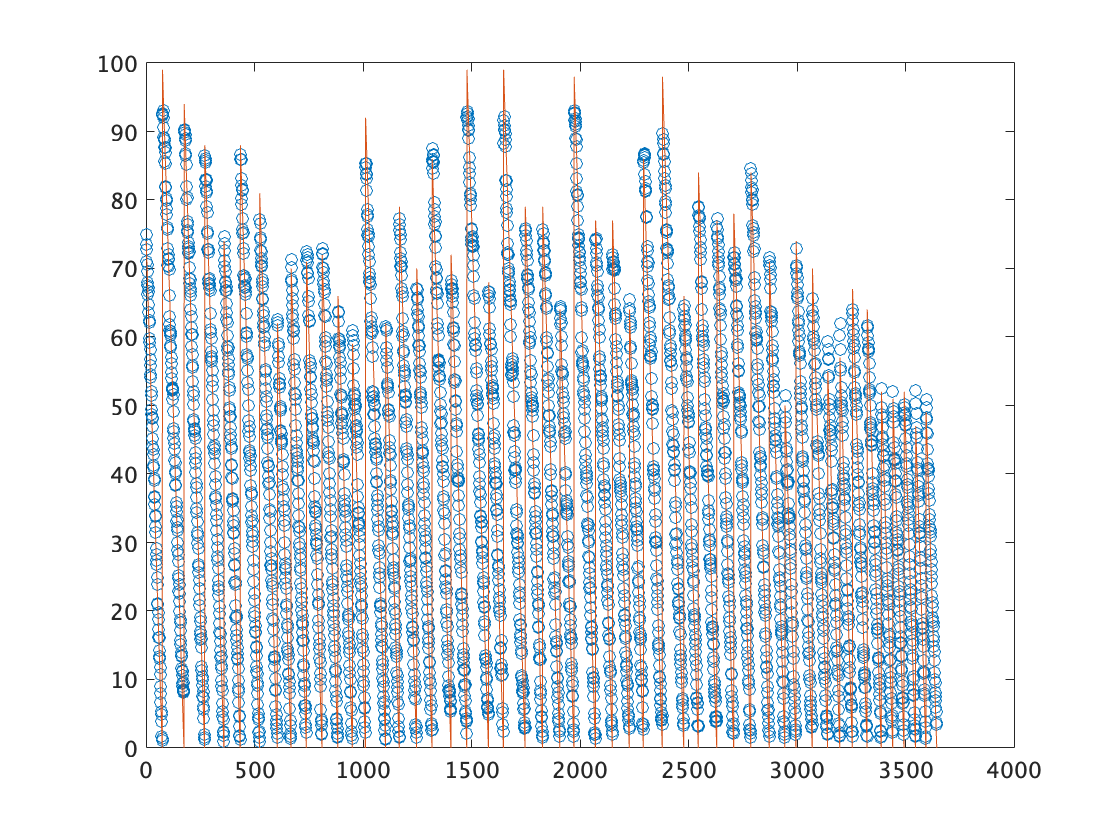


figure
plot(predTrain,'o');
hold on
plot(trainData.Y,'-')
hold off

## 学習データに対しての精度検証２

現時点では各フライトサイクルにおける RUL を予測しているが、ここで RUL は本来であれば傾き -1 で単調減少することを反映させて、傾き -1 の直線に近似する。その時の cycle = 1 (初回フライト時) の Y の値をその unit の RUL とする。

% unit 番号が変わるタイミングでデータを分割
diffUnit = diff(trainData.Unit);
idx = find(abs(diffUnit)>0)+1;
idx = [1;idx;height(trainData)];

% それぞれの unit で近似処理
%  y = - x + C;
Clist = 99:-1:40;
error = zeros(size(Clist));
Cfix = zeros(size(idx,1)-1,1);
Ctrue = zeros(size(idx,1)-1,1);
for jj=1:size(idx,1)-1
    tmp = predTrain(idx(jj):idx(jj+1)-1);
    for ii=1:length(Clist)
        C = Clist(ii);
        yy = C - (0:length(tmp));
        error(ii) = norm(yy-tmp);
    end
    [~,minidx] = min(error);
    Cfix(jj) = Clist(minidx);
    Ctrue(jj) = trainData.Y(idx(jj));
end

cycle = 1 (初回フライト時) の Y の値をその unit の RUL として誤差評価

[Cfix, Ctrue]

ans =     76    74
    99    99
    94    94
    88    88
    76    74
    88    88
    81    81
    63    62
    70    70
    75    71


sqrt(mean((Cfix-Ctrue).^2))

ans = 1.7786

## テスト用データに対しての予測

load(fullfile(modeldir,"model.mat"),'mdl');
predTest = mdl.predict(subtestData);

上と同様に直線近似を行い、cycle = 1 (初回フライト時) の Y の値をその unit の RUL とする。

% こちらは各 unit で 40 cycle 分なので分けやすい
predTest = reshape(predTest, 40, []);
x1 = 0:39;
%  y = - x + C;
Clist = 99:-1:40;
error = zeros(size(Clist));
Cfix = zeros(size(predTest,2),1);
for jj=1:size(predTest,2)
    for ii=1:length(Clist)
        C = Clist(ii);
        yy = C - x1;
        error(ii) = norm(yy-predTest(:,jj));
    end
    [~,idx] = min(error);
    Cfix(jj) = Clist(idx);
end

結果の出力

unit = reshape(testData.Unit, 40, []);
filename = reshape(testData.DS, 40, []);

output = table(filename(1,:)',unit(1,:)',Cfix,'VariableNames',["filename","unit","Y"]);
writetable(output, fullfile(subdir, "submission.csv"))

提出済の結果との等価性チェック

tmp = readtable(fullfile(subdir,"submission_ensemble_alldata_v9.csv"));
sqrt((mean((tmp.Y(1:48)-Cfix).^2)))

ans = 0

特徴量作成（Model Health Parameters の傾き）を計算（最適化を用いて曲線近似）するために使用する目的関数。

function errors = myfun(x,data)

a = x(1);
b = x(2);


yfit = 1-exp((a*data(:,1)).^b);
errors = norm(data(:,2)-yfit);

end
